# Classify Objects with Pretrained Network

In this exercise, you will explore different pretrained networks and see how they classify different objects. 

clear
addpath(genpath(pwd))

Pick one of three networks to load in.

net = alexnet;

## Inspect network

% Inspect network's layers
% analyzeNetwork(net)
net.Layers

ans =   25x1 Layer array with layers:

     1   'data'     Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'    Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    Grouped Convolution           2 groups of 128 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0


% Inspect the different classes available
% Look at the last layer in the network
classes = net.Layers(end).ClassNames

classes = 1000×1 cell array
    {'tench'                   }
    {'goldfish'                }
    {'great white shark'       }
    {'tiger shark'             }
    {'hammerhead'              }
    {'electric ray'            }
    {'stingray'                }
    {'cock'                    }
    {'hen'                     }
    {'ostrich'                 }
    {'brambling'               }
    {'goldfinch'               }
    {'house finch'             }
    {'junco'                   }
    {'indigo bunting'          }
    {'robin'                   }
    {'bulbul'                  }
    {'jay'                     }
    {'magpie'                  }
    {'chickadee'               }
    {'water ouzel'             }
    {'kite'                    }
    {'bald eagle'              }
    {'vulture'                 }
    {'great grey owl'          }
    {'European fire salamander'}
    {'common newt'             }
    {'eft'                     }
    {'spotted salamander'      }
    {'axolotl' 

## To Do: Classify the images in the folder

Try reading in a few of the images and display them

im = imread(['02-Images',filesep,'file01.jpeg']);
imshow(im)

Based on your network, you'll have to look at the first layer to determine how to resize your image. Use the following command to see and set the input size

net.Layers(1).InputSize

ans =    227   227     3


inputSize = net.Layers(1).InputSize(1:2);
% inputSize = 227 227

Now resize your images to be consistent with inputSize 

im = imresize(im, inputSize);

classify your resized images

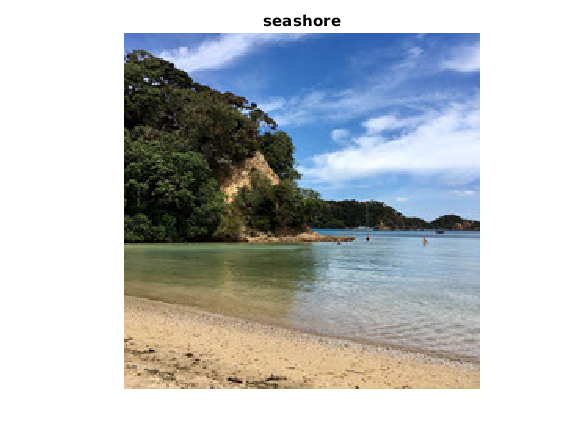

label = classify(net, im);
title(char(label))

## Run this in a loop using datastore

A datastore can be used when we have lots of images that we can't load into memory at once. It serves as a way to point to a collection of images when we need them without reading them directly into MATLAB at once. (See [imageDatastore documentation](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.imagedatastore.html) for more details)

You can manage and read images with the datastore:

- `hasdata: `determines if data is available to read

- `read`: imports images one-by-one in consecutive order (used for loops)

- `readimage`: imports a select image

- `readall`: imports all images

Create the datastore for the entire image directory and use the read function in a loop. 

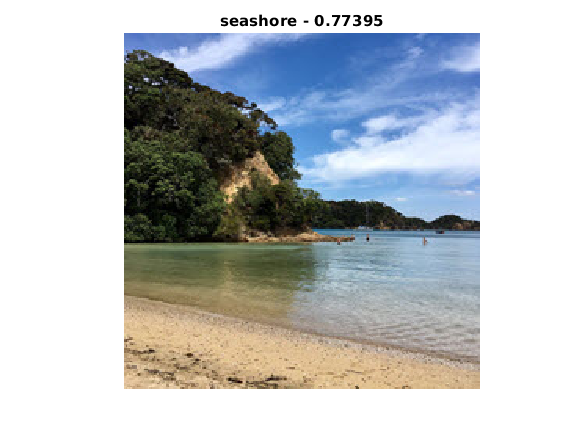

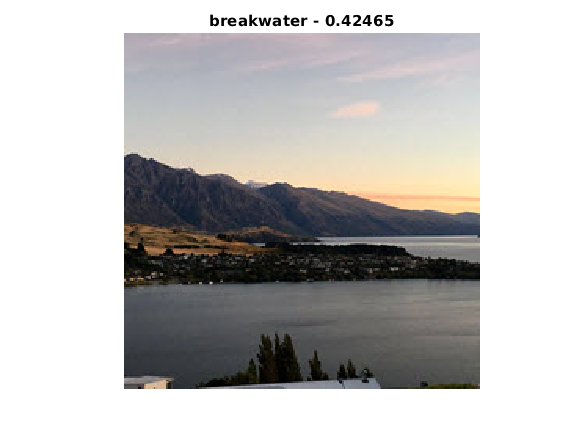

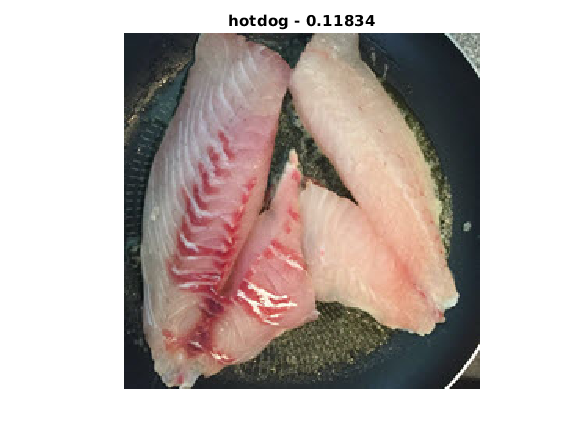

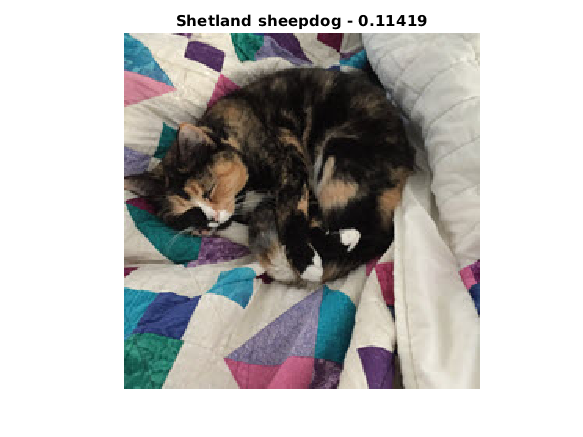

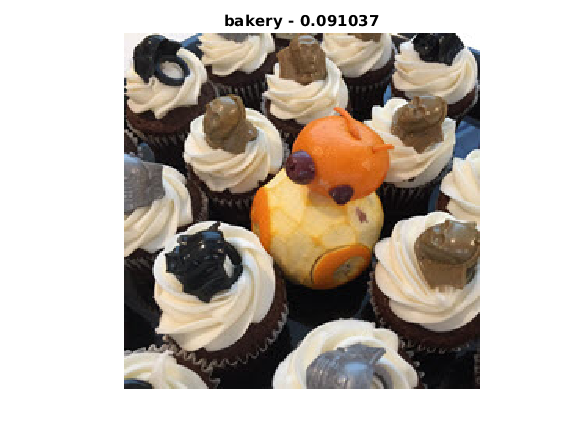

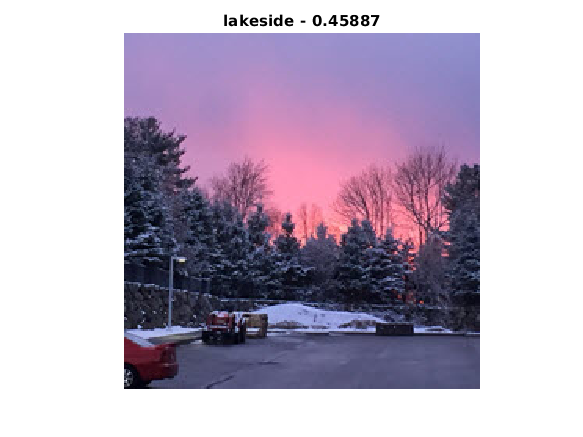

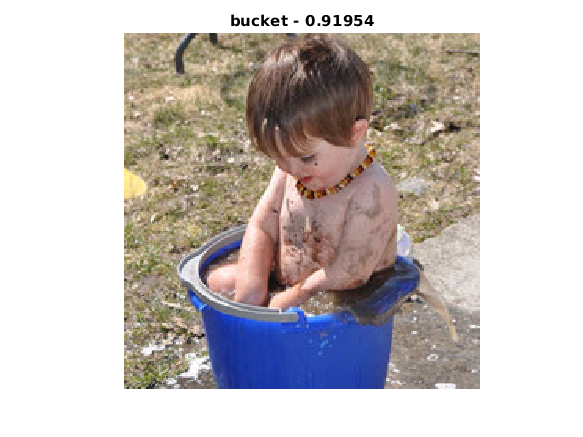

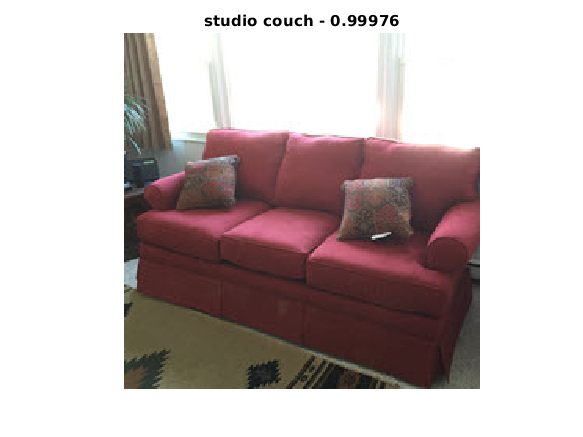

imgPath = '02-Images';
ids = imageDatastore(imgPath);

while hasdata(ids)
    
    im = read(ids);
       
    %You may have to change resize parameters based on what size the input layer requires
    imR = imresize(im, inputSize);  
    
    [label,score] = classify(net,imR);
    maxScore = max(score);
    figure
    imshow(im)
    title([char(label) ' - ' num2str(maxScore)])
   
end    


ids.reset

## To Do: Classify pictures from the internet

Find pictures on the internet and classify them!

URL = ''; %[ADD CODE HERE]
filename = '.jpg'; %[ADD CODE HERE]
websave(filename, URL);

Error using websave (line 95)
Expected URL to be nonempty.


im = imread(filename);
im = imresize(im, inputSize);
classify(net,im)

*Copyright 2019 The MathWorks, Inc.*